# Day 6 - Initial Data Visualizations

[lr_accel, lr_gyro] = parsePowerSenseData_1('12inchtest_90bpm.csv');

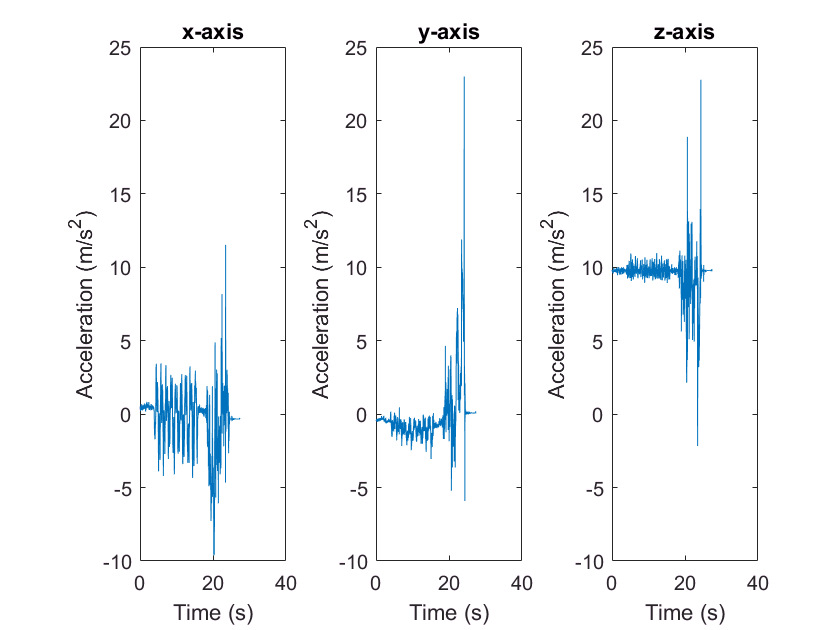

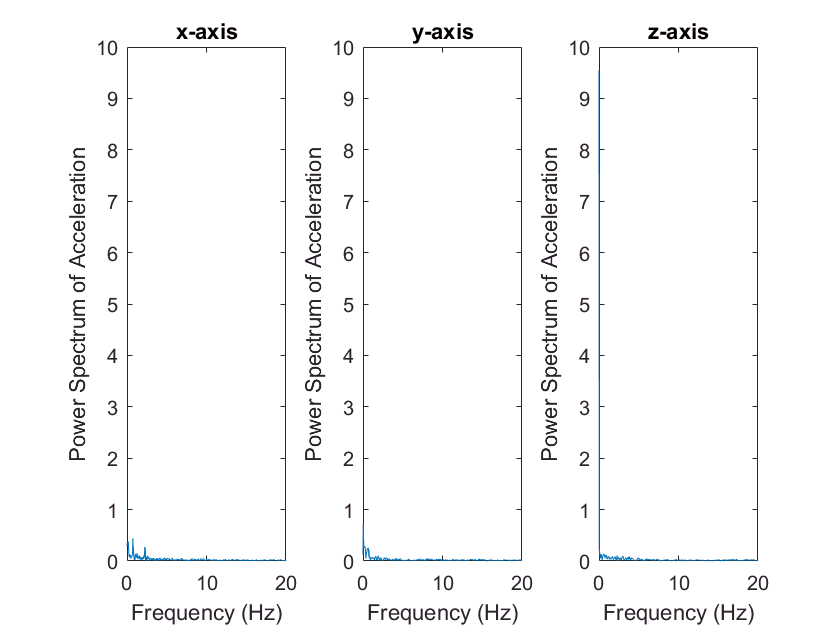

makeAccelerometerPlots(lr_accel,[],true)

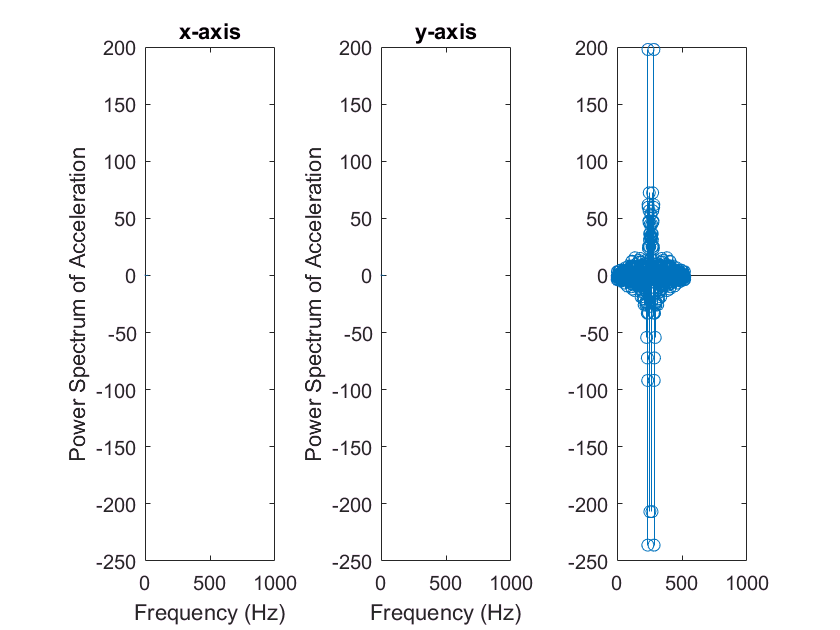

startcut = 280;
endcut = 800;

x_accel = lr_accel(:,2);
x_accel = x_accel(startcut:endcut);
plot(x_accel)
fft_x = real(fft(x_accel));
fft_xshift = fftshift(fft_x);

[~, i] = max(fft_xshift);
stem(fft_xshift)

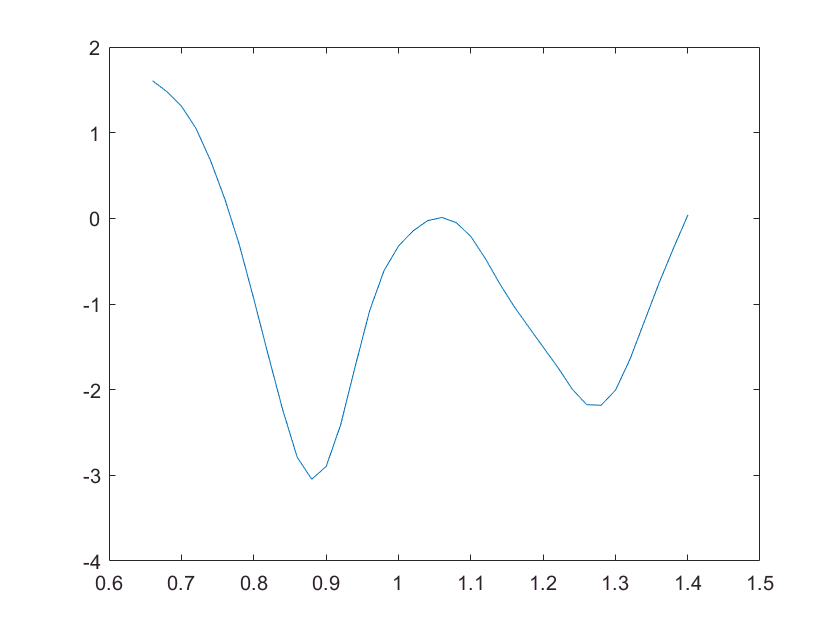

Fs = 1/lr_accel(2,1)-(lr_accel(1,1));

% make_freq_plot(x_accel, Fs)


h = [1/4 1/4 1/4 1/4];          % moving average shape
x_accel = conv(x_accel, h);     % moving average convolution
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_accel = conv(x_accel,h);      % move the average again
x_accel = x_accel(1:(end-length(h)+1)); % adjusting for conv
x_times = lr_accel(:,1);        % grab times column
x_times = x_times(startcut:endcut);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times

period1 = 34:71;
xacc_int = x_accel(period1);
xtime_int = x_times(period1);

velocity = cumtrapz(xtime_int, xacc_int);
position = cumtrapz(xtime_int, velocity);

figure
plot(xtime_int, xacc_int)

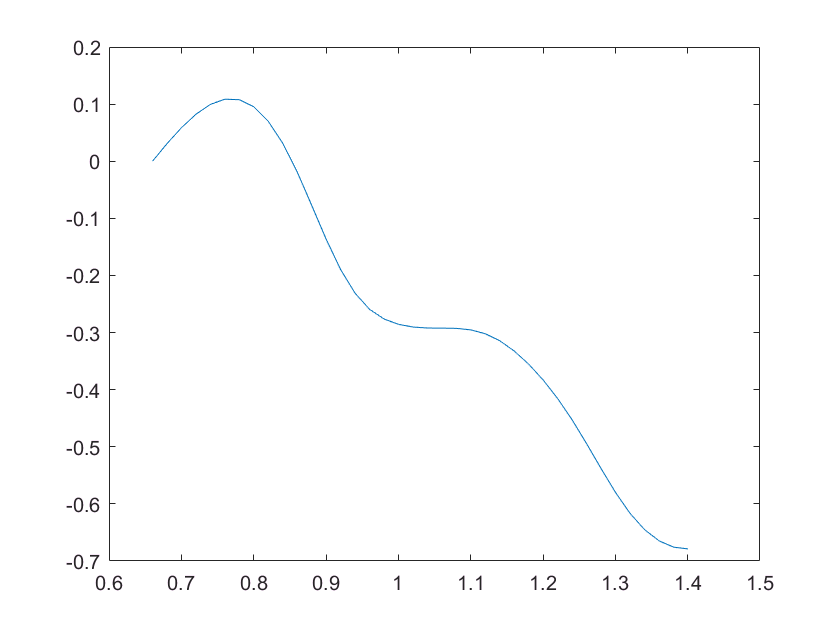

plot(xtime_int, velocity)

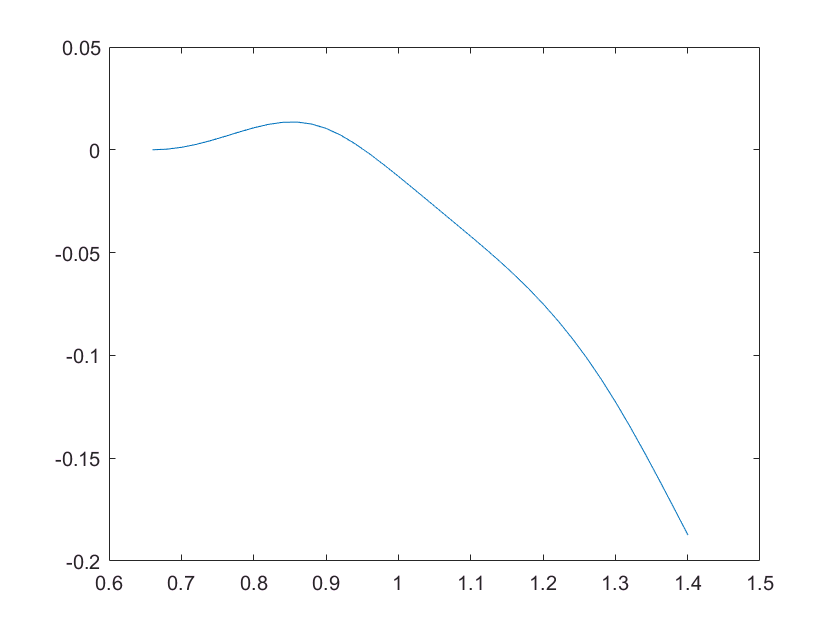

plot(xtime_int, position) 

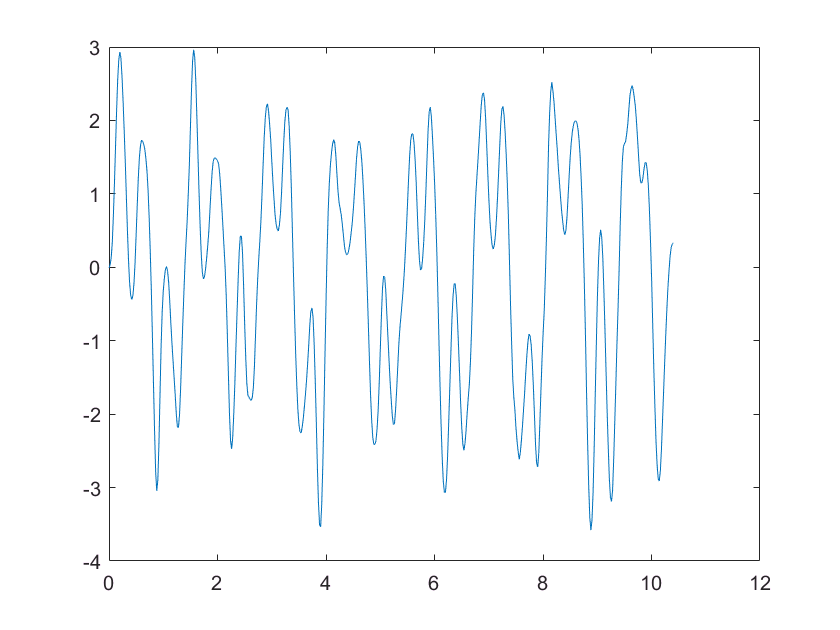

plot(x_times, x_accel)

# Square Conducting Analysis

[square_accel, square_gyro] = parsePowerSenseData_1('square90bpm.csv');

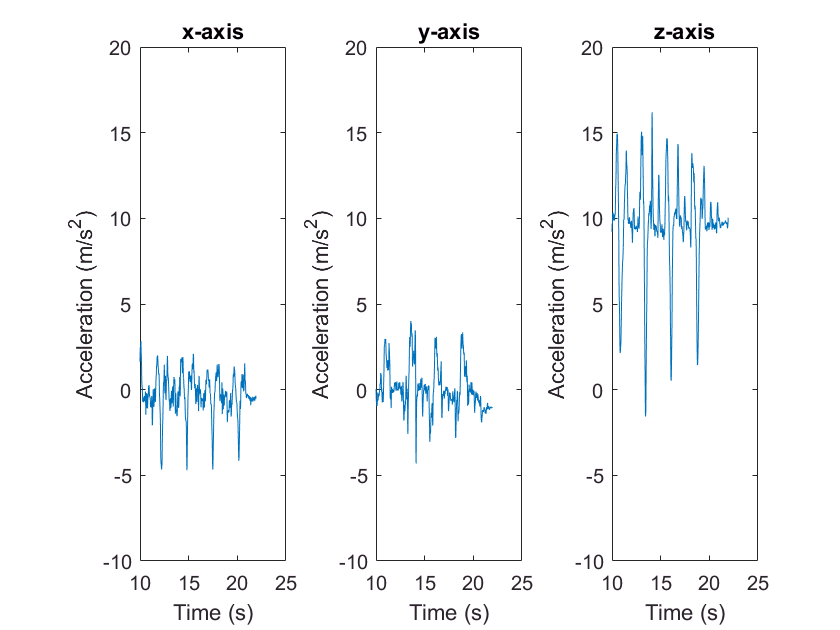

figure
makeAccelerometerPlots(square_accel,[], false)
ylim([-10 20])
xlim([10 25])

x_times = square_accel(:,1);    % grab times column
x_times = x_times(100:750);     % cutoff bad data
x_times = x_times-x_times(1);   % center unex times
z_accel_square = square_accel(100:750,4)

z_accel_square =    10.1558
   10.3542
   10.3261
   10.3071
   10.3063
   10.2402
   10.3644
   10.3688
   10.0557
    9.9102


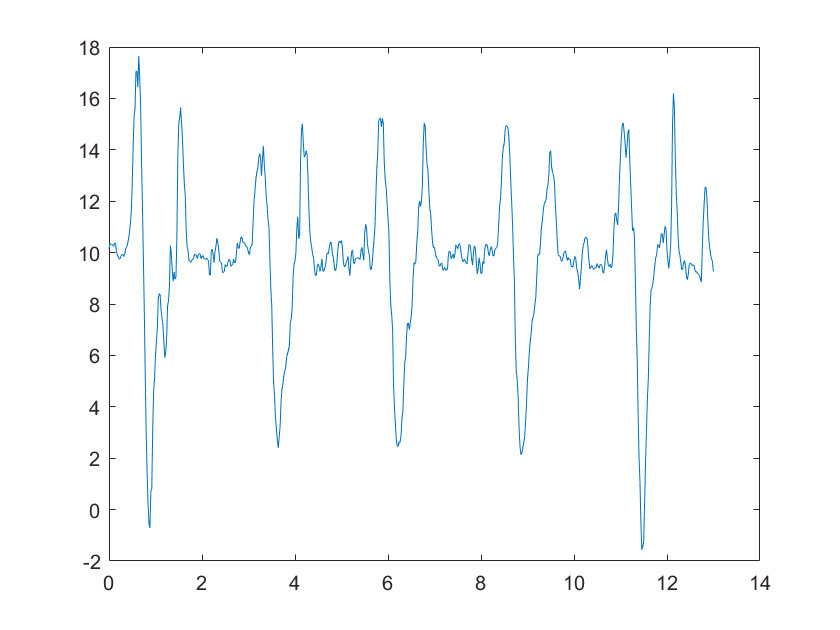

figure
plot(x_times, z_accel_square)

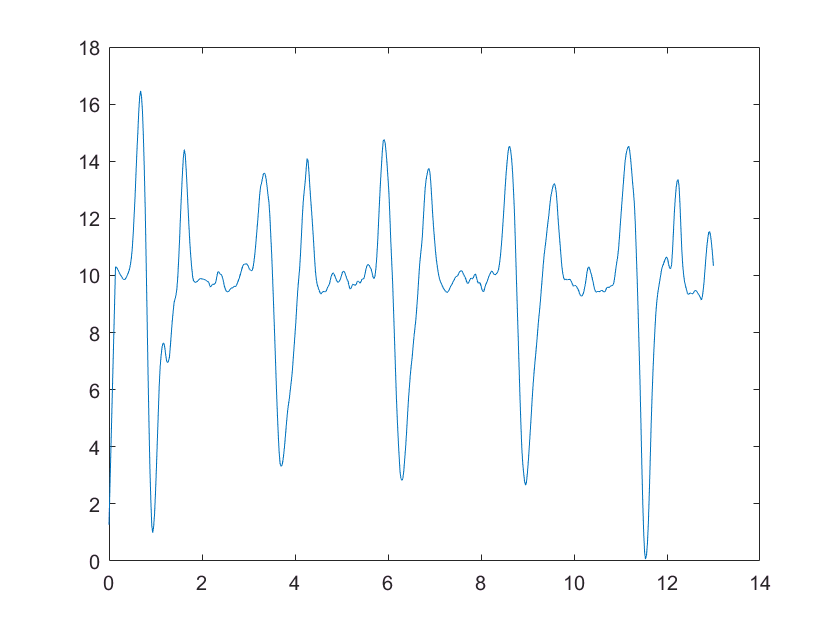


num = 8;
h = ones(1, num)./num;

%xacc = conv(xacc, h);
zacc = conv(z_accel_square, h);
%xacc = xacc(1:end-length(h)+1);
zacc = zacc(1:end-length(h)+1);

plot(x_times,zacc)


binarySignal = zacc < 6;
leadingEdges1 = find(diff(binarySignal) >= 1);
beatOneInd = leadingEdges1

beatOneInd =     43
   181
   309
   442
   572



% THIS MAKES THE ARRAY OF TIMES
beatOneTimes =[]


beatOneTimes =

     []



for i = 1 : size(beatOneInd)
    indexBeat = beatOneInd(i);
    beatOneTimes(i) = x_times(indexBeat);
end
beatOneTimes % THIS IS THE ARRAY OF TIMES

beatOneTimes =     0.8399    3.5995    6.1592    8.8188   11.4185



% beat error analysis
known_beat = 90;              % bpm
sec_per_beat = 60/known_beat; % seconds per beat
actual_bpm = 60./((beatOneTimes(2:end) - beatOneTimes(1:end-1))./4)

actual_bpm =    86.9679   93.7622   90.2373   92.3198


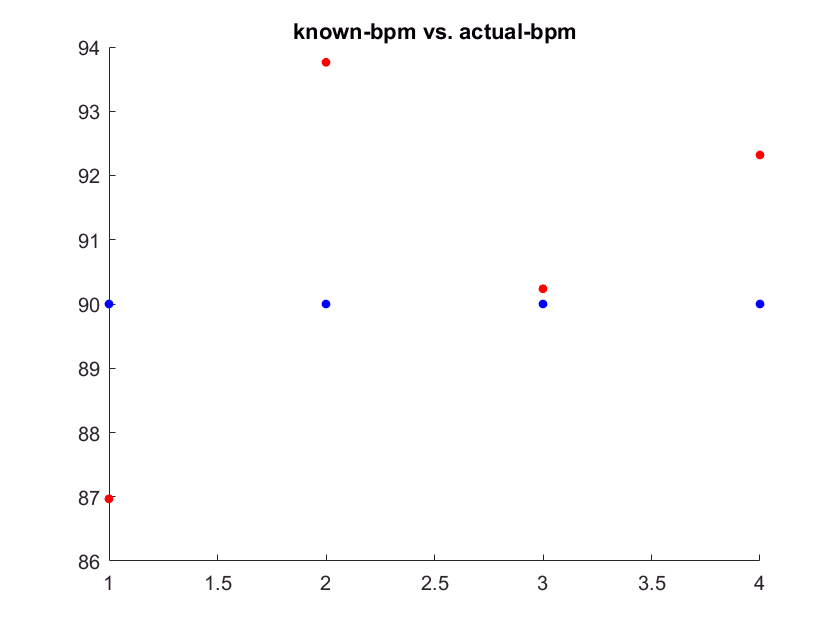


% plot error
figure
hold on
dot = 15;
plot(actual_bpm, 'r.', 'markersize', 15)
plot(known_beat.*ones(length(actual_bpm)), 'b.', 'markersize', 15)
title('known-bpm vs. actual-bpm')



binarySignal = zacc > 12;
leadingEdges4 = find(diff(binarySignal) >= 1);
beat4Ind = leadingEdges4

beat4Ind =     27
    77
   161
   208
   291
   339
   425
   473
   551
   608


%[Minima, MinIdx] = findpeaks(-zacc)